clear
clc
n=100000;

f_opt=importdata("scores_opt.mat");

mu=mean(f_opt);
sig=std(f_opt);
figure

i=1;
%subplot(2,2,i)
histogram(f_opt(:,i))

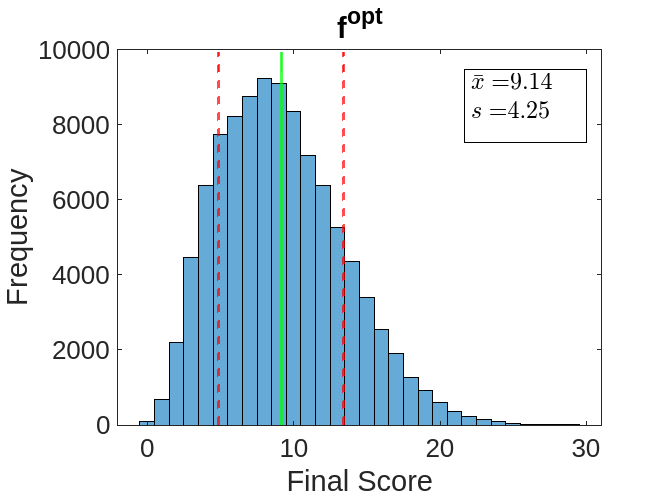

xline(mu(i),LineWidth=2,Color='g')
xline(mu(i)+sig(i),LineWidth=2,Color='r',LineStyle='--')
xline(mu(i)-sig(i),LineWidth=2,Color='r',LineStyle='--')
xlabel('Final Score')
ylabel('Frequency')
str=['$\bar{x}=$',num2str(mu(i),'%.2f'),newline,'$s=$',num2str(sig(i),'%.2f')];
annotation('textbox','Position',[0.7,0.69,0.18,0.17],'String',str,'FitBoxToText','on','Interpreter','latex','FontSize',18)
title('f^{opt}')
set(gca,'fontsize', 20)